# EMBEDDED SYSTEMS II

# Practical Four

## Generate Lookup Tables

generatate look up tabels for a single cycle of a wave

it should have a minimum of 128 vlaues ranging from 0 to 1023

### SINUSOIDAL WAVE

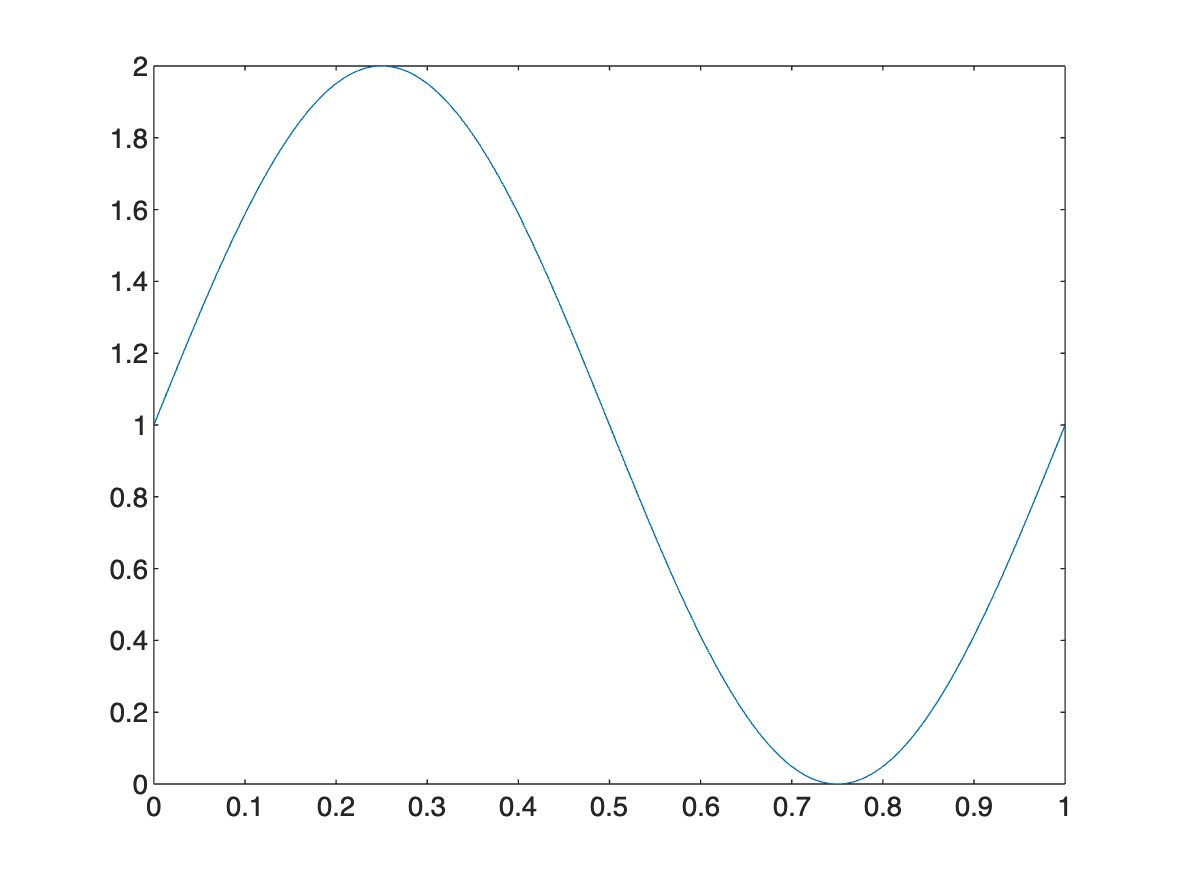

clearvars

% params
samplingFrequency1 = 1000;   % Sampling frequency [Hz]
duration1 = 1;               % Duration of the sine wave [s]
frequency1 = 1;          % Frequency of the sine wave [Hz]
amplitude1 = 1;              % Amplitude of the sine wave

% Generate Time Vector
%start:increment:stop
t1 = 0:1/samplingFrequency1:duration1;

signal1 = amplitude1 * sin(2 * pi * frequency1 * t1)+1;

plot(t1, signal1)

% Define the input values (128 values from 0 to 1023)
arrayInputSIN = linspace(1, 128, 128);

for i = 1:length(arrayInputSIN)
    time = ((1/frequency1)/128)*i;
    arrayOutputSIN(i) = floor(1023*(sin(2 * pi * frequency1*time)+1)/2);
end

% Create lookup table using containers.Map
lookupTable = containers.Map(arrayInputSIN, arrayOutputSIN);

% Test lookup table
input = 77;
output = lookupTable(input);
disp(['Input: ', num2str(input), ' Output: ', num2str(output)]);

Input: 77 Output: 206


### SAWTOOTH WAVE

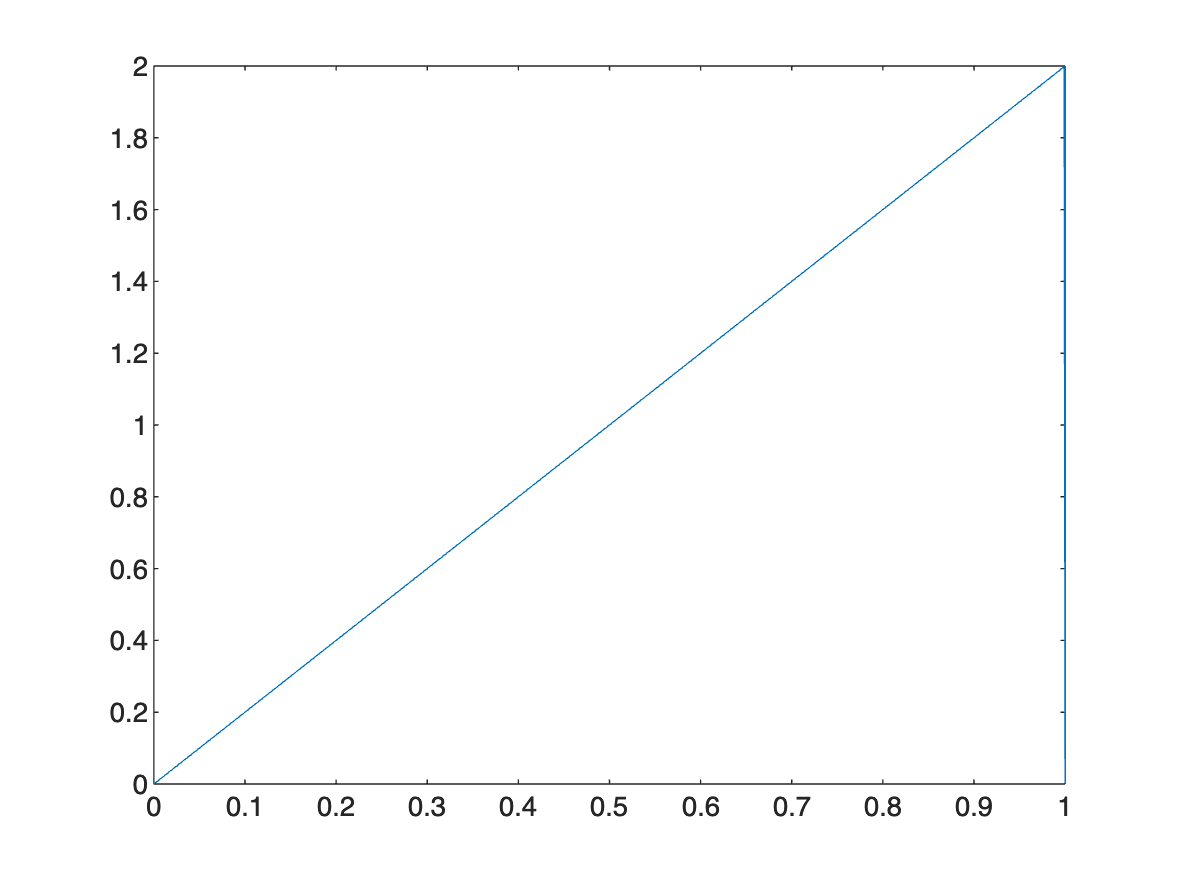

% Define Parameters
samplingFrequency2 = 1000;   % Sampling frequency [Hz]
duration2 = 1;               % Duration of the sine wave [s]
frequency2 = 1;          % Frequency of the sine wave [Hz]
amplitude2 = 1;              % Amplitude of the sine wave

% Generate Time Vector
%start:increment:stop
t2 = 0:1/samplingFrequency2:duration2;

signal2 = amplitude2 * sawtooth(2 * pi * frequency2 * t2)+1;

plot(t2, signal2)


% Define the input values (128 values from 0 to 1023)
arrayInputSAW = linspace(1, 128, 128);

for i = 1:length(arrayInputSAW)
    time = ((1/frequency2)/128)*i;
    arrayOutputSAW(i) = floor(1023*(sawtooth(2 * pi * frequency2*time)+1)/2);
end

% Create a lookup table using containers.Map
lookupTable = containers.Map(arrayInputSAW, arrayOutputSAW);

% Test the lookup table
input = 77;
output = lookupTable(input);
disp(['Input: ', num2str(input), ' Output: ', num2str(output)]);

Input: 77 Output: 615


### TRIANGULAR WAVE

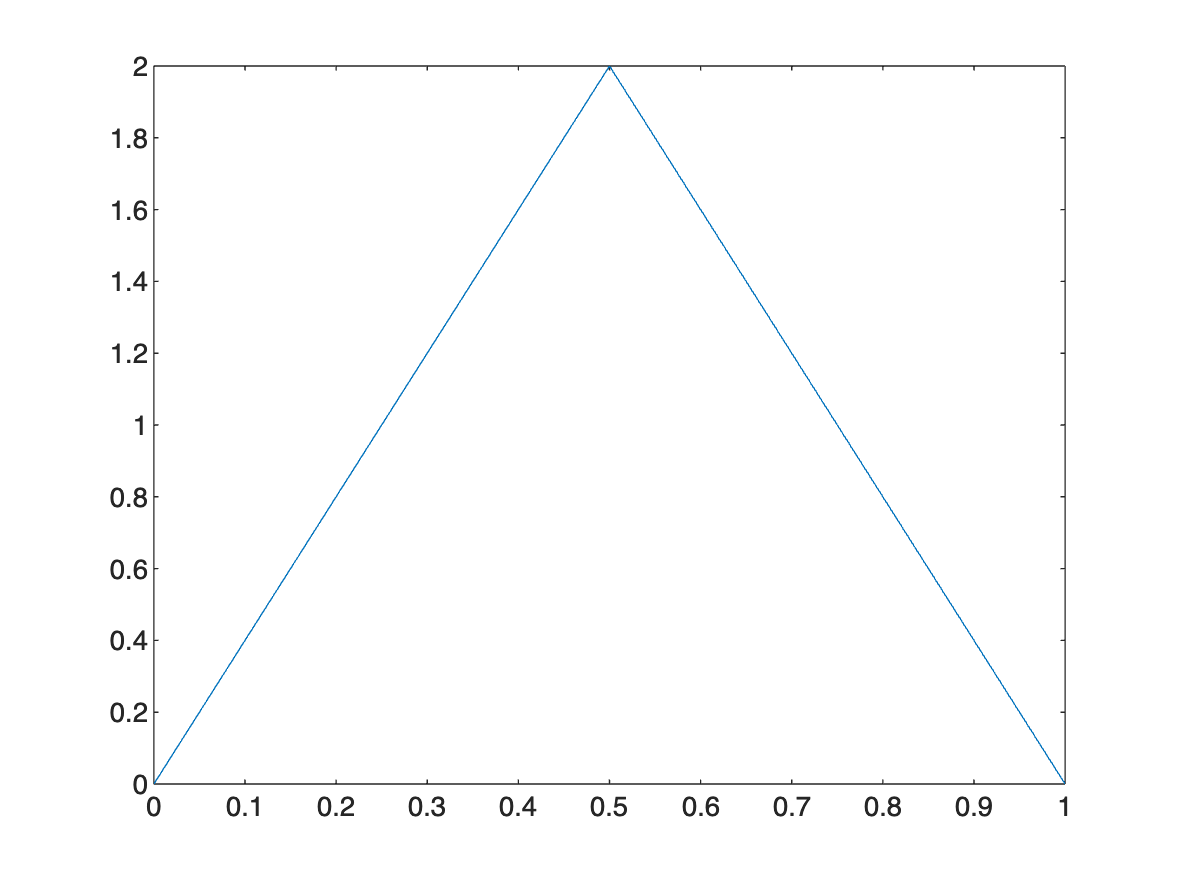


% Define Parameters
samplingFrequency3 = 1000;   % Sampling frequency [Hz]
duration3 = 1;               % Duration of the sine wave [s]
frequency3 = 1;          % Frequency of the sine wave [Hz]
amplitude3 = 1;              % Amplitude of the sine wave

% Generate Time Vector
%start:increment:stop
t3 = 0:1/samplingFrequency3:duration3;

signal3 = amplitude3 * sawtooth(2 * pi * frequency3 * t3, 0.5)+1;

plot(t3, signal3)



% Define the input values (128 values from 0 to 1023)
arrayInputTRI = linspace(1, 128, 128);

for i = 1:length(arrayInputTRI)
    time = ((1/frequency3)/128)*i;
    arrayOutputTRI(i) = floor(1023*(sawtooth(2 * pi * frequency3*time, 0.5)+1)/2);
end

% Create a lookup table using containers.Map
lookupTable = containers.Map(arrayInputTRI, arrayOutputTRI);

% Test the lookup table
input = 77;
output = lookupTable(input);
disp(['Input: ', num2str(input), ' Output: ', num2str(output)]);

Input: 77 Output: 815






% Convert the array to a comma-separated string
TRIstring = join(string(arrayOutputTRI), ',');
SAWstring = join(string(arrayOutputSAW), ',');
SINstring = join(string(arrayOutputSIN), ',');

% Display the result
disp(TRIstring);

15,31,47,63,79,95,111,127,143,159,175,191,207,223,239,255,271,287,303,319,335,351,367,383,399,415,431,447,463,479,495,511,527,543,559,575,591,607,623,639,655,671,687,703,719,735,751,767,783,799,815,831,847,863,879,895,911,927,943,959,975,991,1007,1023,1007,991,975,959,943,927,911,895,879,863,847,831,815,799,783,767,751,735,719,703,687,671,655,639,623,607,591,575,559,543,527,511,495,479,463,447,431,415,399,383,367,351,335,319,303,287,271,255,239,223,207,191,175,159,143,127,111,95,79,63,47,31,15,0


disp(SAWstring);

7,15,23,31,39,47,55,63,71,79,87,95,103,111,119,127,135,143,151,159,167,175,183,191,199,207,215,223,231,239,247,255,263,271,279,287,295,303,311,319,327,335,343,351,359,367,375,383,391,399,407,415,423,431,439,447,455,463,471,479,487,495,503,511,519,527,535,543,551,559,567,575,583,591,599,607,615,623,631,639,647,655,663,671,679,687,695,703,711,719,727,735,743,751,759,767,775,783,791,799,807,815,823,831,839,847,855,863,871,879,887,895,903,911,919,927,935,943,951,959,967,975,983,991,999,1007,1015,0


disp(SINstring);

536,561,586,611,635,659,683,707,730,752,774,795,816,835,855,873,890,906,922,936,950,962,973,984,993,1000,1007,1013,1017,1020,1022,1023,1022,1020,1017,1013,1007,1000,993,984,973,962,950,936,922,906,890,873,855,835,816,795,774,752,730,707,683,659,635,611,586,561,536,511,486,461,436,411,387,363,339,315,292,270,248,227,206,187,167,149,132,116,100,86,72,60,49,38,29,22,15,9,5,2,0,0,0,2,5,9,15,22,29,38,49,60,72,86,100,116,132,149,167,187,206,227,248,270,292,315,339,363,387,411,436,461,486,511
